# Value-at-Risk Forecast Evaluation

We will now turn to the evaluation of the forecasts that were created in the previous sections.

### Loading the Data

We will upload the VaR estimates from the previous two sections in order to evaluate these forecasts. This means that the forecasts evaluated here are those for the series we have chosen in the previous sections. In the example in class, this was the S&P500 series. Nevertheless, one can easily change this by selecting the EUR/USD in the previous scripts.

clear all
clc
load HS_VaR
load FHS_VaR
VaRs = [HS_VaR FHS_VaR];

## Exercise 75.a - HITs

In the previous exercises, we already saw the meaning and importance of HITs. A HIT is a VaR violation, and so it is an indicator variable for the return less than the VaR forecast (recalling that the forecast for period t is stored in position t-1). Because we have many VaRs stored in our `VaRs` matrix, we will use the `bsxfun` function to apply the < operator (`@lt`) for all series at once. Let's check how the `bsxfun` function works:

help bsxfun

  bsxfun  Binary Singleton Expansion Function
    C = bsxfun(FUNC,A,B) applies the element-by-element binary operation
    specified by the function handle FUNC to arrays A and B, with implicit
    expansion enabled. 
 
    FUNC can be one of the following built-in functions:
 
    Note: For R2016b and later, you can directly use operators instead of
    bsxfun, since the operators independently support implicit expansion of
    arrays with compatible sizes. 
 
                @plus           Plus
                @minus          Minus
                @times          Array multiply
                @rdivide        Right array divide
                @ldivide        Left array divide
                @power          Array power
                @max            Binary maximum
                @min            Binary minimum
                @rem            Remainder after division
                @mod            Modulus after division
                @atan2	    

We can therefore use the operator `@lt` to apply the < logical comparison between the elements in` r `and `VaRs`.

% Checking the "<" condition with "bsxfun":
HITs = bsxfun(@lt,r(2:end),VaRs(1:end-1,:));
% The expected HIT percentage of "VaRs" columns:
alpha = [.05 .01 .05 .01];
labels = {'HS VaR 5%','HS VaR 1%','FHS VaR 5%','FHS VaR 1%'};

### Analysing Unconditional HITs

The most basic test is an unconditional test using the average HIT probability, which should match alpha. As we saw this morning, this test is easy to implement using a regression. All we have to do is regress the HITs on a constant and test if the constant is equal to alpha. Alternatively, we can regress HITs-alpha and test whether the constant is equal to zero.

% Doing these unconditional T-Tests:
for i=1:4
    % Regressing HIT-alpha on a constant:
    [excess,tstat] = ols(HITs(:,i) - alpha(i),[],1);
    % Checking if the constant is zero:
    disp(labels{i})
    disp(tstat)
end

HS VaR 5%


      -6.7521



HS VaR 1%


      -3.3758



FHS VaR 5%


      -5.3387



FHS VaR 1%


      -1.9809



As we can see it above, only the 1% VaR from FHS passes this test. The negative value for the other VaR methods indicates that they are, unconditionally, too conservative. 

### Dynamic Conditional HITs

The Dynamic Quantile (DQ) test includes lagged values and so generalizes the previous test. The first version includes a single lag while the second looks at 10 lags. To make it easier to get the lags of HITs-alpha we will use the `newlagmatrix` function:

help newlagmatrix

  Construction of a matrix of lags (X) and a vector (Y) for use in an
  autoregression
 
  USAGE:
      [Y,X]=newlagmatrix(Y,NLAGS,C)
 
  INPUTS:
      Y     - The dependant variable(Tx1)
      NLAGS - The number of lags(scalar)
      C     - [OPTIONAL] 1 if you want to include a constant; 0 is default
 
  OUTPUTS:
      Y     - (n-p) by 1 vector of contemporaneous values
      X     - (n-p) by p (or p+1 if c=1) matrix of lags and possibly constant.  The
                matrix is of the form [constant(if included) t-1 t-2 ... t-p]
 
  COMMENTS:
      Original name, 'lagmatrix' conflicts with a Matlab file, so newlagmatrix
      replaces original



Now that we know how the `newlagmatrix` function works, let's proceed to the DQ test using a single lag:

% Doing the DQ test for each of "VaRs" columns:
for i=1:4
    [y,X] = newlagmatrix(HITs(:,i) - alpha(i),1);
    [excess,tstat,~,~,vcvw] = ols(y,X,1);
    % Building the Wald statistic:
    test_stat = excess' * inv(vcvw) * excess;
    % Calculating the P-Val:
    pval = 1 - chi2cdf(test_stat,6);
    disp(labels{i})
    disp(pval)
end

HS VaR 5%


   2.9754e-14



HS VaR 1%


    0.0027209



FHS VaR 5%


   1.8159e-06



FHS VaR 1%


      0.20044



As it was the case with the unconditional VaRs evaluation, when 1 lag is included, only the 1% FHS is not rejected. That is, 1% VaR from FHS passes this test. 

We then proceed to doing the same thing but now considering 10 lags rather than just one. 

% Doing the DQ test for each of "VaRs" columns:
for i=1:4
    [y,X] = newlagmatrix(HITs(:,i) - alpha(i),10,0);
    [excess,tstat,~,~,vcvw] = ols(y,X,1);
    % Building the Wald statistic:    
    test_stat = excess' * inv(vcvw) * excess;
    % Calculating the P-Val:    
    pval = 1 - chi2cdf(test_stat,15);
    disp(labels{i})
    disp(pval)
end

HS VaR 5%


     0



HS VaR 1%


   9.2376e-06



FHS VaR 5%


     0



FHS VaR 1%


     0



When 10 lags are included all models are rejected (i.e. we are able to reject the null of all coefficients being jointly zero in all models). This makes sense as a model would need to be either extremely close to the true DGP or very complex/parametrized in order to capture the dependency on these 10 lags simultaneously.

## Exercise 75.b - Unconditional Testing using the Bernoulli

The unconditional test can be improved using the Bernoulli. Let's recall how this unconditional evaluation of VaR using the Bernoulli works:

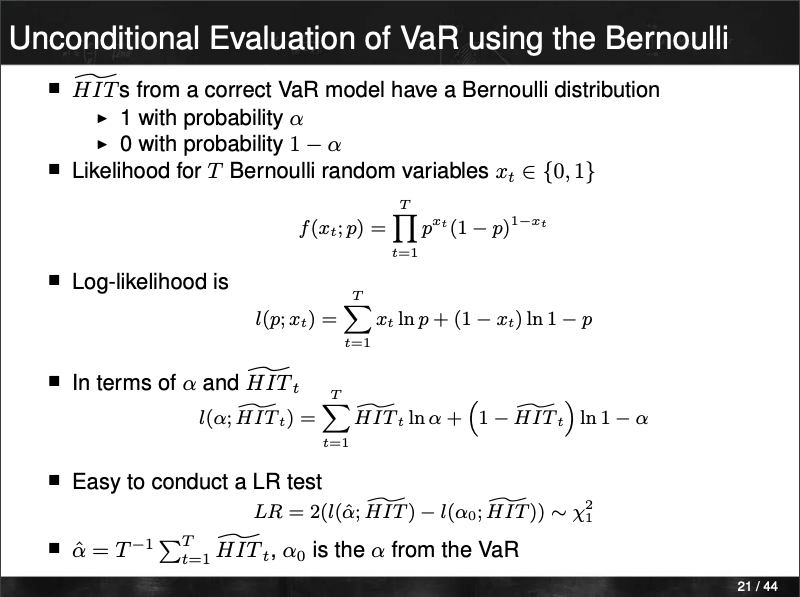

So let's do this test!

% Doing the test for each of "VaRs" columns:
for i=1:4
    % Selecting the model:
    y = HITs(:,i);
    % Getting the true p (under h0):
    p_0 = alpha(i);
    % Estimating model p:
    p_hat = mean(y);
    % Calculating the likelihoods:
    log_lik = sum(y.*log(p_hat) + (1-y).*log(1-p_hat));
    log_lik_0 = sum(y.*log(p_0) + (1-y).*log(1-p_0));
    % Building the test statistic:
    test_stat = 2 * (log_lik - log_lik_0);
    % Checking the p-value:
    pval = 1 - chi2cdf(test_stat, 1);
    disp(labels{i})
    disp(pval)
end

HS VaR 5%


   2.9614e-08



HS VaR 1%


    0.0073236



FHS VaR 5%


   4.7784e-06



FHS VaR 1%


     0.083049



We can see that the result of the unconditional evaluation of VaR using the Bernoulli reinforces the result from the simple unconditional VaR analysis. Using this test, we find that only the 1% FHS is not rejected.

## Exercise 75.c - Christoffersen's Conditional Bernoulli Test

Christoffersen's test is the evaluation of conditional VaR using the Bernoulli described in the lecture slides. As we did it above, let's recall how this test looks like:

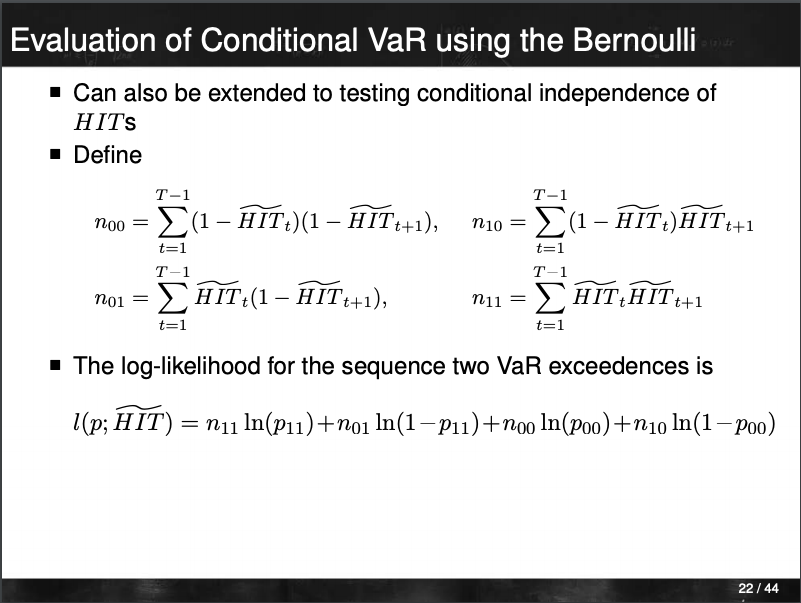

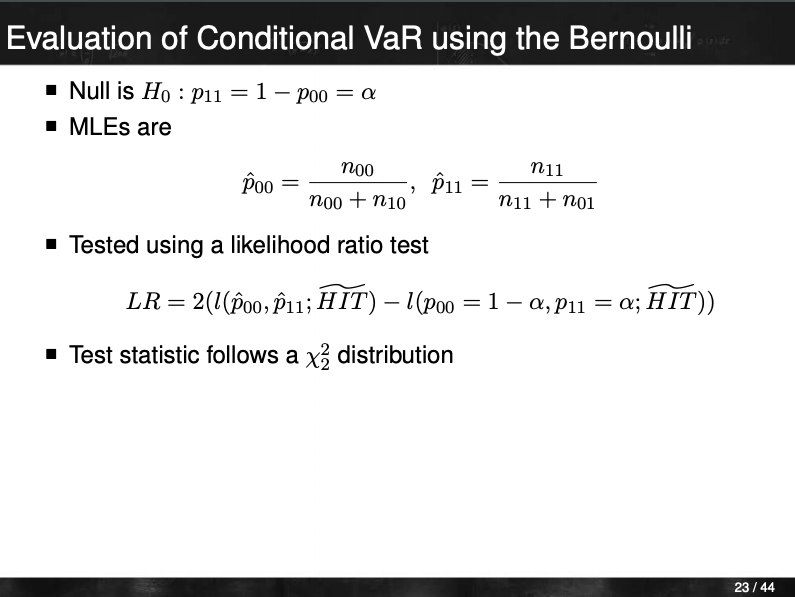

% Doing the test for each of "VaRs" columns:
for i=1:4
    % Selecting the model:
    a = alpha(i);
    y = HITs(:,i);
    % Getting the n's:
    n00 = (1 - y(1:end-1))'*(1 - y(2:end));
    n01 = (1 - y(1:end-1))'*y(2:end);
    n10 = y(1:end-1)'*(1 - y(2:end));
    n11 = y(1:end-1)'*y(2:end);
    % Estimating the probabilities:
    p00 = n00 ./ (n00 + n01);
    p11 = n11 ./ (n11 + n10);
   % Calculating the likelihoods:
    log_lik  = n00*log(p00)+n01*log(1-p00)+n11*log(p11)+n10*log(1-p11);
    log_lik_0 = n00*log(1-a)+n01*log(a)+n11*log(a)+n10*log(1-a);
    % Now the LR statistic:
    test_stat = 2 * (log_lik - log_lik_0);
    % Checking the p-value:
    pval = 1 - chi2cdf(test_stat, 2);
    disp(labels{i})
    disp(pval)
end

HS VaR 5%


   2.4121e-12



HS VaR 1%


   0.00013389



FHS VaR 5%


   1.3443e-06



FHS VaR 1%


    0.0039062



The results are similar to the ones we found in other tests. Nevertheless, now even the 1% FHS model is (marginally) rejected at 5% significance. 